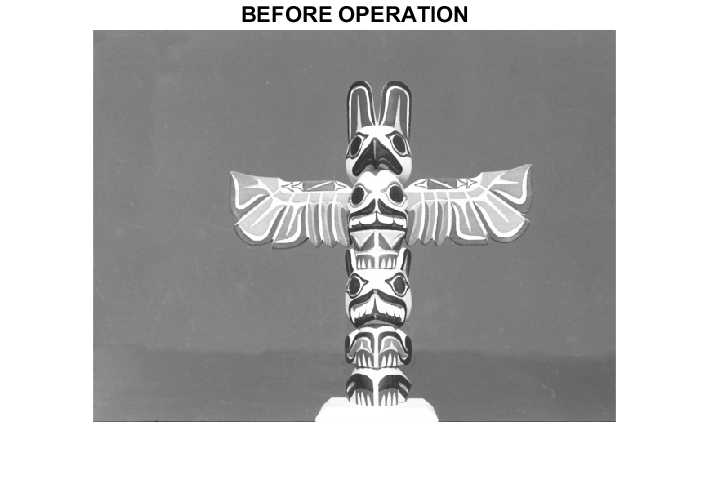

%ques 5. performing the rotation operation on an image

A=imread('C:\Users\tvasu\Desktop\totem.png');
figure,imshow(A),title('BEFORE OPERATION');

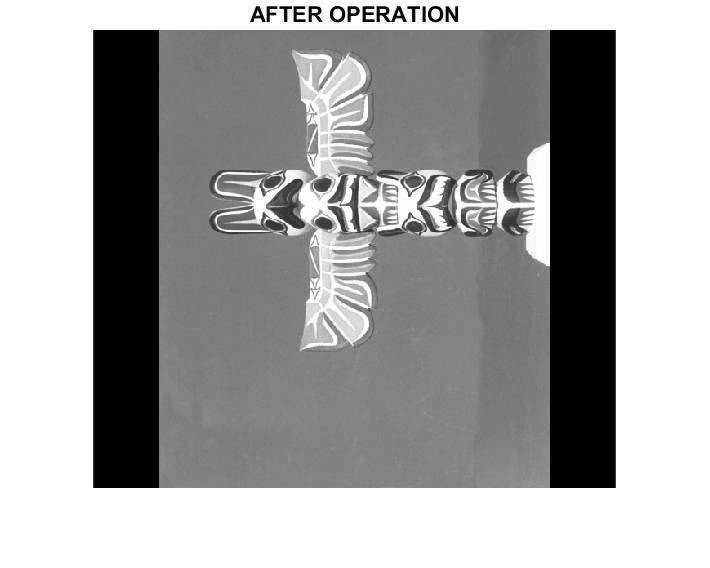

x1=zeros([size(A,1)*size(A,2) 1]);
x2=zeros([size(A,2)*size(A,1) 1]);
deg=90; %Specify the degree
C=uint8(zeros([size(A,1) size(A,2) 3 ]));%Change the image size
m=1; %Find the midpoint
midx=ceil((size(C,1)+1)/2);
midy=ceil((size(C,2)+1)/2);

for i=1:size(A,1)
    i1=i-midx;
    for j=1:size(A,2)
        %convert from cartesian to polar
        [t,r]=cart2pol(i1,j-midy);
        %Convert from radians to degree and add the degree value
        t1=rad2deg(t)+deg;
        %Convert from degree to radians
        t=deg2rad(t1);
        %Convert to Cartesian Co-ordinates
        [x,y]=pol2cart(t,r);
        x1(m)=round(x+midx);
        x2(m)=round(y+midy);
        m=m+1;       
    end
end
%check whether the values are within the image size.
x1(find(x1 < 1))=1;
x2(find(x2 < 1))=1;
n=1;
for i=1:size(A,1)
    for j=1:size(A,2)
        C(x1(n),x2(n),:)=A(i,j,:);
        n=n+1;
    end
end
figure,imshow(C),title('AFTER OPERATION');